# 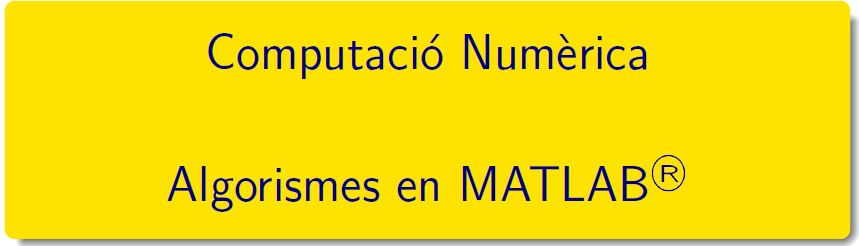

# Pràctica 2 - Activitat 1: Conceptes Bàsics (revisió pràctica 1)

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

### Practiquem les funcions

#### Exercici 6, pàgina 23. [Funcions anònimes](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

**6**  Avalueu les funcions  $\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$ per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$ 

Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. Feu un joc de proves prenent $2^{-n},5^{-n},7^{-n},10^{-n}, \dots$

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

clearvars
f = @(x)sqrt(x.^2+1)-1;
g = @(x)x.^2./(sqrt(x.^2+1)+1);

k = 1:30;
v = 8.^(-k);

R = [k;v;f(v);g(v)]';
v2 = 2.^(-k);
R2 = [k;v2;f(v2);g(v2)]';
T = array2table(R, 'VariableNames', {'k', '8^-k', 'f(k)', 'g(k)'});
disp(T)

    k        8^-k          f(k)          g(k)   
    __    __________    __________    __________

     1         0.125     0.0077822     0.0077822
     2      0.015625    0.00012206    0.00012206
     3     0.0019531    1.9073e-06    1.9073e-06
     4    0.00024414    2.9802e-08    2.9802e-08
     5    3.0518e-05    4.6566e-10    4.6566e-10
     6    3.8147e-06     7.276e-12     7.276e-12
     7    4.7684e-07    1.1369e-13    1.1369e-13
     8    5.9605e-08    1.7764e-15    1.7764e-15
     9    7.4506e-09             0    2.7756e-17
    10    9.3132e-10             0    4.3368e-19
    11    1.1642e-10             0    6.7763e-21
    12    1.4552e-11             0    1.0588e-22
    13     1.819e-12             0    1.6544e-24
    14    2.2737e-13             0    2.5849e-26
    15    2.8422e-14             0     4.039e-28
    16    3.5527e-15          

T2 = array2table(R2, 'VariableNames', {'k', '8^-k', 'f(k)', 'g(k)'});
disp(T2)

    k        8^-k          f(k)          g(k)   
    __    __________    __________    __________

     1           0.5       0.11803       0.11803
     2          0.25      0.030776      0.030776
     3         0.125     0.0077822     0.0077822
     4        0.0625     0.0019512     0.0019512
     5       0.03125    0.00048816    0.00048816
     6      0.015625    0.00012206    0.00012206
     7     0.0078125    3.0517e-05    3.0517e-05
     8     0.0039062    7.6294e-06    7.6294e-06
     9     0.0019531    1.9073e-06    1.9073e-06
    10    0.00097656    4.7684e-07    4.7684e-07
    11    0.00048828    1.1921e-07    1.1921e-07
    12    0.00024414    2.9802e-08    2.9802e-08
    13    0.00012207    7.4506e-09    7.4506e-09
    14    6.1035e-05    1.8626e-09    1.8626e-09
    15    3.0518e-05    4.6566e-10    4.6566e-10
    16    1.5259e-05    1.1642

v3 = 3.^(-k);
R3 = [k;v3;f(v3);g(v3)]';
T3 = array2table(R3, 'VariableNames', {'k', '8^-k', 'f(k)', 'g(k)'});
disp(T3)

    k        8^-k          f(k)          g(k)   
    __    __________    __________    __________

     1       0.33333      0.054093      0.054093
     2       0.11111     0.0061539     0.0061539
     3      0.037037    0.00068564    0.00068564
     4      0.012346    7.6205e-05    7.6205e-05
     5     0.0041152    8.4675e-06    8.4675e-06
     6     0.0013717    9.4084e-07    9.4084e-07
     7    0.00045725    1.0454e-07    1.0454e-07
     8    0.00015242    1.1615e-08    1.1615e-08
     9    5.0805e-05    1.2906e-09    1.2906e-09
    10    1.6935e-05     1.434e-10     1.434e-10
    11     5.645e-06    1.5933e-11    1.5933e-11
    12    1.8817e-06    1.7704e-12    1.7704e-12
    13    6.2723e-07    1.9673e-13    1.9671e-13
    14    2.0908e-07     2.176e-14    2.1856e-14
    15    6.9692e-08    2.4425e-15    2.4285e-15
    16    2.3231e-08    2.2204

v4 = 10.^(-k);
R4 = [k;v4;f(v4);g(v4)]';
T4 = array2table(R4, 'VariableNames', {'k', '8^-k', 'f(k)', 'g(k)'});
disp(T4)

    k      8^-k        f(k)          g(k)   
    __    ______    __________    __________

     1       0.1     0.0049876     0.0049876
     2      0.01    4.9999e-05    4.9999e-05
     3     0.001         5e-07         5e-07
     4    0.0001         5e-09         5e-09
     5     1e-05         5e-11         5e-11
     6     1e-06    5.0004e-13         5e-13
     7     1e-07     4.885e-15         5e-15
     8     1e-08             0         5e-17
     9     1e-09             0         5e-19
    10     1e-10             0         5e-21
    11     1e-11             0         5e-23
    12     1e-12             0         5e-25
    13     1e-13             0         5e-27
    14     1e-14             0         5e-29
    15     1e-15             0         5e-31
    16     1e-16             0         5e-33
    17     1e-17             0         5e-35
    18  

#### Exercici 8, pàgina 23. [Funcions en Live script](https://es.mathworks.com/help/matlab/ref/function.html)

`function f = nom_fun(``arglist``)`

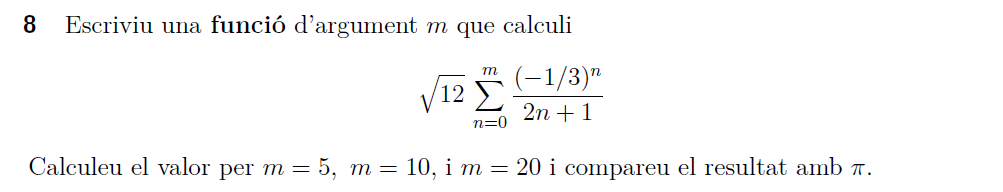

sum1 = 0

sum1 = 0

for n = 0:5
    sum1 = sum1 + (-1/3)^n/(2*n+1);
end
sum1 = sum1*sqrt(12)

sum1 = 3.1413


sum2 = 0

sum2 = 0

for n = 0:10
    sum2 = sum2 + (-1/3)^n/(2*n+1);
end
sum2 = sum2*sqrt(12)

sum2 = 3.1416


sum3 = 0

sum3 = 0

for n = 0:20
    sum3 = sum3 + (-1/3)^n/(2*n+1);
end
sum3 = sum3*sqrt(12)

sum3 = 3.1416


R = [sum1;sum2;sum3;abs(pi-sum1); abs(pi-sum2); abs(pi-sum3)]'

R =     3.1413    3.1416    3.1416    0.0003    0.0000    0.0000


## 2. Algorismes: Estabilitat numèrica i problemes ben condicionats

**(ja eren al document prac01)**

#### Exercici 11, pàgina 23. **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos mètodes iteratius diferents:

	            
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

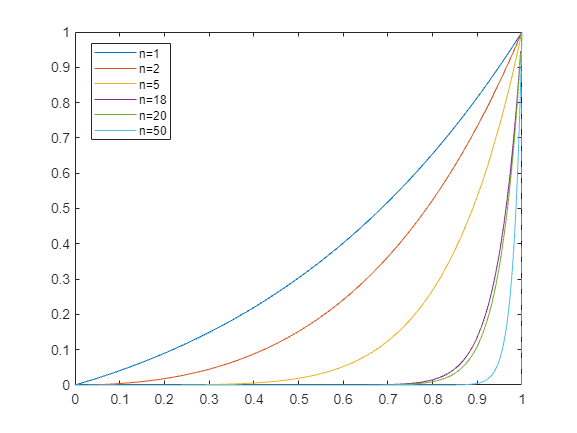

F = @(x,n)x.^n.*exp(x-1);
fplot({@(x)F(x, 1), @(x)F(x, 2), @(x)F(x, 5), @(x)F(x, 18), @(x)F(x, 20),  @(x)F(x, 50)}, [0,1])
legend("n=1", "n=2", "n=5", "n=18", "n=20", "n=50")
legend("Location", "Best")

- apartat a)

J(50) = 0

J =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for n = 50:-1:2          %No li puc posar 50:1 perquè vagi cap enrere numèricament. El que fem és posar el -1 per indicar-li que el pas és de -1.
    J(n-1) = (1-J(n))/n;
end

- apartat b)

I(1) = 1/exp(1) %No existeix el valor "e", per tant el fem amb exp(1)

I = 0.3679

for n = 2:50
    I(n) = 1-n*I(n-1);
end

- valor aproximat per integració numèrica

for n = 1:50
    K(n) = integral(@(x)x.^n.*exp(x-1),0,1);
end

- Taula comparativa de resultats

R = [1:50; J(50:-1:1); I; K]';
T = array2table(R, 'VariableNames', {'n', 'APARTAT A', 'APARTAT B', 'APROXIMACIÓ MATLAB'});
disp(T)

    n     APARTAT A     APARTAT B     APROXIMACIÓ MATLAB
    __    _________    ___________    __________________

     1           0         0.36788          0.36788     
     2        0.02         0.26424          0.26424     
     3        0.02         0.20728          0.20728     
     4    0.020417         0.17089          0.17089     
     5    0.020842         0.14553          0.14553     
     6    0.021286          0.1268           0.1268     
     7    0.021749         0.11238          0.11238     
     8    0.022233         0.10093          0.10093     
     9    0.022739        0.091612         0.091612     
    10    0.023268        0.083877         0.083877     
    11    0.023823        0.077352         0.077352     
    12    0.024404        0.071773         0.071773     
    13    0.025015        0.066948         0.066948     
    14  

- Taula comparativa d'errors

R2 = [1:50; abs(J(50:-1:1)-K); abs(J(50:-1:1)-K)./K; abs(I-K); abs(I-K)./K]';
T2 = array2table(R2, 'VariableNames', {'i', 'Ea1', 'Er1', 'Ea2', 'Er2'});
disp(T2)

    i        Ea1         Er1          Ea2           Er2    
    __    _________    ________    __________    __________

     1      0.36788           1             0             0
     2      0.24424     0.92431    5.5511e-17    2.1008e-16
     3      0.18728     0.90351    8.3267e-17    4.0172e-16
     4      0.15048     0.88053    2.7756e-16    1.6241e-15
     5      0.12469     0.85679    1.4988e-15    1.0299e-14
     6      0.10552     0.83213    8.9373e-15    7.0482e-14
     7     0.090634     0.80647    6.2658e-14    5.5754e-13
     8     0.078699     0.77972    5.0113e-13     4.965e-12
     9     0.068874     0.75179    4.5102e-12    4.9231e-11
    10     0.060609     0.72259    4.5101e-11    5.3771e-10
    11      0.05353     0.69202    4.9612e-10    6.4137e-09
    12     0.047369     0.65998    5.9534e-09    

## 3. Pràctica

#### Exercici 10, pàgina 23.  Sumar sèrie $e^x$

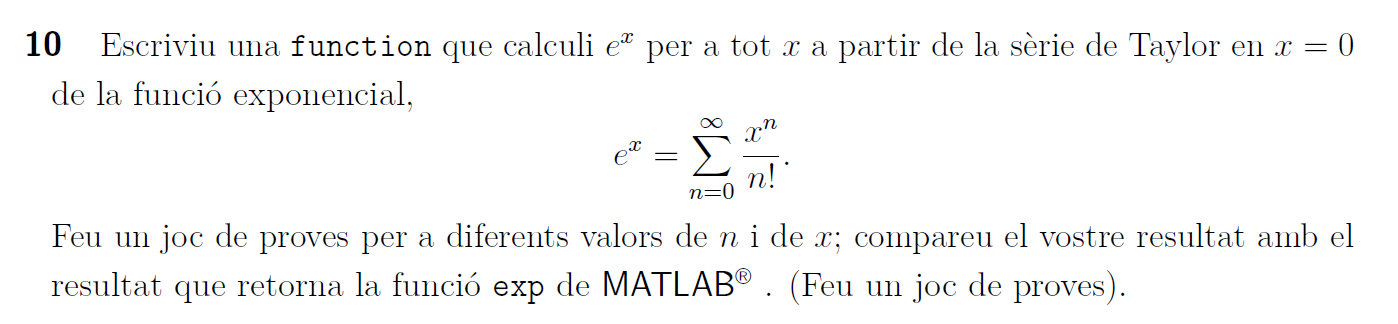     

%FER PER LA SETMANA VINENT (Compte amb x>10, error aritmètic (fer
%(x/1*x/2*x/3...x/n en comptes del x^n/n) i compte amb les x < 0, que la
%sèrie no és igual)

#### Exercici 12, pàgina 23.  Sumar sèrie $\sin(x)$

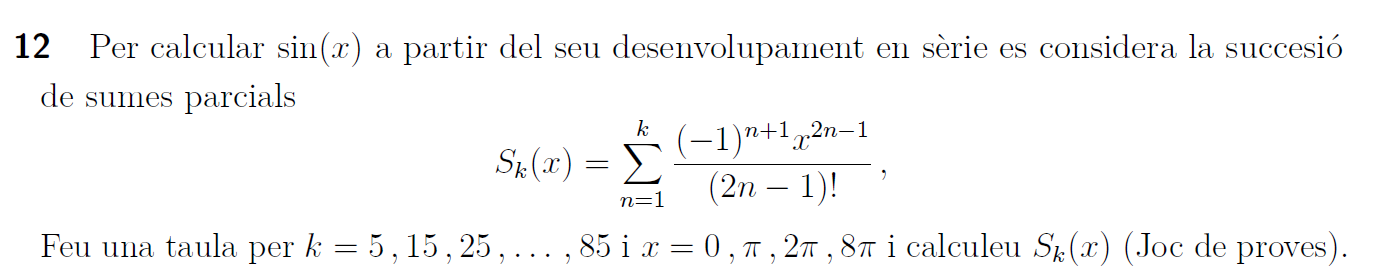

%FER PER LA SETMANA VINENT

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`